# Cargar información de NDVI RCAT

## Declaracion de variables sobre el área de estudio

import matlab.io.hdfeos.*

%clearvars -except area_estudio;
clear;
close all;

disp(">>> Declarando variables...ok")

>>> Declarando variables...ok



%directorio de datos
dir_data = "D:\DATA\";

% % %Ventana para el mapa region hidrografica rio panuco
% lon_mapa = [-98.7 -96.8];
% lat_mapa = [19.8 21.9];

% lon_mapa = [-99.5 -95.2];
% lat_mapa = [17.8 22.5];

lon_mapa = [-98.8 -96.8];
lat_mapa = [19.9 21.8];

% % 
% % %cuadrante de inicio y tamaño del area de estudio
coord_1k_v6_inicio = [3950 3950];
coord_1k_v6_tam = [455 850];
% % 
%h08v06
coord_1k_v7_inicio = [3950 0];
coord_1k_v7_tam = [455 30];
% % 
 ndvi_tam = [455 880];


## Obtener matrices de latitud longitud

% Datos sin el disco duro
% info_hdf = f_infohdfs2table(dir_data,"MOD13Q1");
% Datos con el disco duro
info_hdf = f_infohdfs2table("G:\DATA\","MOD13Q1");

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1084 archivos



[num_registros,~] = size(info_hdf);

if (num_registros > 0)
    [lat,lon,ndvi]=f_get_latlon(info_hdf,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);
end

>>>>> Obteniendo latitud y longitud


## **Crear el área de estudio**

% crear matriz de 0 y 1 que delimitan el área de estudio
ae = exist("study_area","var");
if ae == 0
    ae = exist("study_area.mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load study_area;
        disp(">>> Area Lista");
    else
        disp("Creando area de estudio");
        study_area = f_create_study_area(dir_data+'KML\Area_study.kml',lat,lon);
        save ("study_area.mat",'study_area');
    end
else
    if( numel(study_area) <= 1)
        disp("La variable area_estudio sera sustituida");
        study_area = f_create_study_area(dir_data+'KML\Area_study.kml',lat,lon);
        save ("study_area.mat",'study_area');
    else
        disp(">>> Área de estudio existente");
    end
end

>>> Cargando área de estudio


>>> Area Lista



ndvi = double(ndvi) .* 0.0001;
ndvi(study_area==false)=nan;

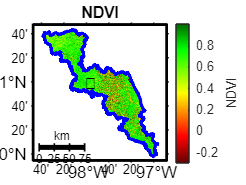


f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI",[],"NDVI","NDVI");
f_draw_kml(dir_data,"Area_study",2,'b',0);


%%promedio_ndvi = mean(ndvi,"all");


## Leer los arreglos de datos

% Realizar la consulta de los datos que se requieren
% tmp = find(  info_hdf.anio == 2022 );
tmp = 1:size(info_hdf,1);
info_consulta = info_hdf(tmp,:);

[num_registros,~] = size(info_consulta);


% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d para la calidad del pixel
arr_ndvi_re = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);

bp=waitbar(0,'Obteniendo información de archivos MODIS'); 
for i=1:num_registros
    [ndvi,~,~,disponibilidad] = f_get_ndvi(info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(study_area==false)=NaN;
    disponibilidad(study_area==false)=NaN;

     %almacenar en el arreglo en 3d
    arr_ndvi(:,:,i) = ndvi;
    arr_ndvi_re(:,:,i) = disponibilidad;
 
    %barra de progreso
    waitbar(i/num_registros,bp,sprintf('Obteniendo información de archivos MODIS (%3.0f%%) ',(i/num_registros*100)));
end
close(bp); 



% for i=1:num_registros
%    % Mostrar algun registro
% idx=11;
% 
% %     f_draw_map(lon_mapa,lat_mapa,lon,lat,arr_ndvi(:,:,idx),"NDVI "+idx,[],"NDVI","NDVI");
%     f_draw_map(lon_mapa,lat_mapa,lon,lat,arr_ndvi_re(:,:,idx),"NDVI "+idx,[],"NDVI","NDVI");
% % end

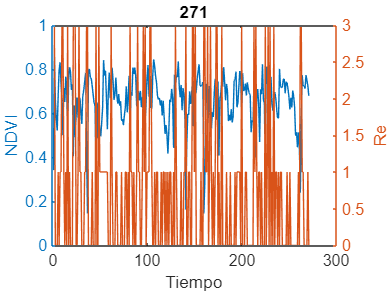


serie = reshape(arr_ndvi(320,400,:),[],1);
% confiabilidad de los datos releabilyti
serie_re = reshape(arr_ndvi_re(320,400,:),[],1);

figure;

yyaxis left 
plot(serie);
title(length(serie))
xlabel('Tiempo')
ylabel('NDVI')
yyaxis right
plot(serie_re);
ylabel('Re')


malos=serie_re(serie_re>=3);
disp("Pixeles Anomalos: "+length(malos));

Pixeles Anomalos: 41


## **Promedio**

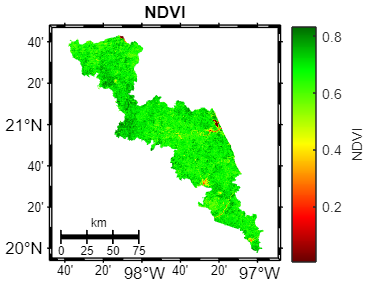

figure;
promedio_ndvi=f_mean_3dpp(arr_ndvi);
f_draw_map(lon_mapa,lat_mapa,lon,lat,promedio_ndvi,"NDVI",[],"NDVI","NDVI");

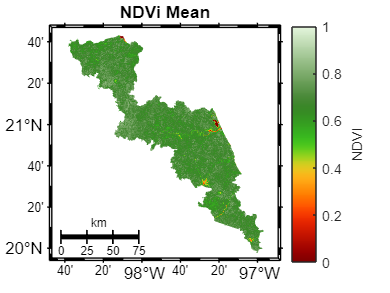


figure;
% Parametros que se reciben
% 5-Titulo del mapa
% 6-Rango del ndvi
% 7-color
% 8-Titulo barra

f_draw_map(lon_mapa,lat_mapa,lon,lat,promedio_ndvi,"NDVi Mean",[0 1],flipud( m_colmap('chloropy',256)),"NDVI" );


figure;


### **Calculo Minimos Maximos y desviacion standar**

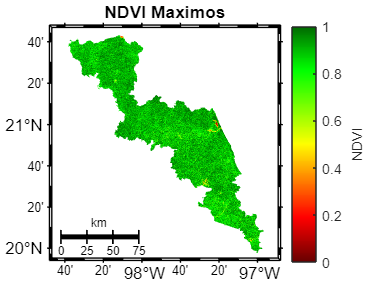

max_ndvi=f_max_3dpp(arr_ndvi);

f_draw_map(lon_mapa,lat_mapa,lon,lat,max_ndvi,"NDVI Maximos",[0 1],"NDVI","NDVI");

min_ndvi=f_min_3dpp(arr_ndvi);

f_draw_map(lon_mapa,lat_mapa,lon,lat,min_ndvi,"NDVI Minimos",[0 1],"NDVI","NDVI");

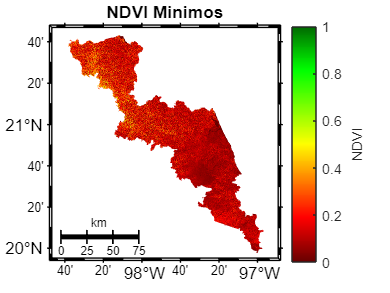

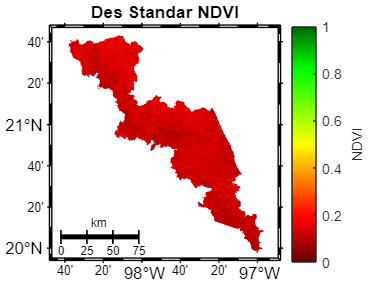



std_ndvi=f_std_3dpp(arr_ndvi);

% f_draw_map(lon_mapa,lat_mapa,lon,lat, std_ndvi,"Desviación Standar NDVI",[0 1],flipud(m_colmap('chloropy',256)),"NDVI");
f_draw_map(lon_mapa,lat_mapa,lon,lat, std_ndvi,"Des Standar NDVI",[0 1],"NDVI","NDVI");

Regresion lineal serie temporal


[a0,a1,ajuste]=f_reglin(1:length(serie),serie')

a0 = 0.6538

a1 = 1.2724e-05

ajuste =     0.6538    0.6538    0.6538    0.6538    0.6538    0.6538    0.6538    0.6539    0.6539    0.6539    0.6539    0.6539    0.6539    0.6539    0.6539    0.6540    0.6540    0.6540    0.6540    0.6540    0.6540    0.6540    0.6540    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6541    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6542    0.6543    0.6543    0.6543    0.6543    0.6543    0.6543    0.6543    0.6543    0.6544    0.6544    0.6544    0.6544


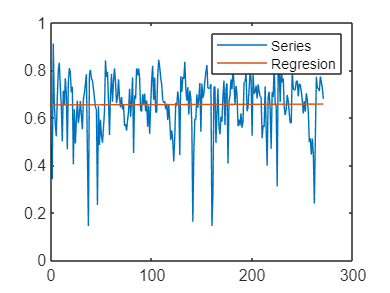

% 1- x cantidad de elementos 
% 2- y 
% 3- x cantidad de elementos
% 4- y elementos de y en regresion lineal
plot(1:length(serie),serie,1:length(serie),ajuste);
legend(["Series" "Regresion"]);

% plot(1:length(serie),serie,1:length(serie),ajuste);
v24 = a0+a1*24

v24 = 0.6541

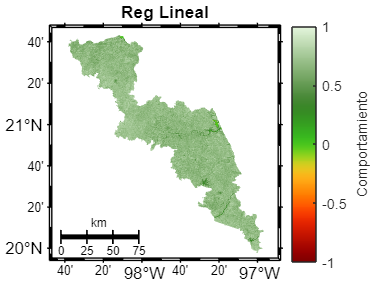

datos=f_reglin_3dpp(arr_ndvi);

figure;

f_draw_map(lon_mapa,lat_mapa,lon,lat,datos,"Reg Lineal",[-1 1],flipud(m_colmap('chloropy',256)),"Comportamiento");

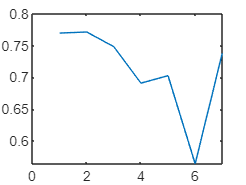


% for i=17:23
%     f_draw_map(lon_mapa,lat_mapa,lon,lat,arr_ndvi(:,:,i) ,"NDVI"+i,[-1 1],"NDVI","NDVI");
%     figure;
% end

serie_cosecha = reshape(arr_ndvi(340,449,17:23),[],1);
plot(1:7,serie_cosecha');


x=info_hdf;

septiembre=find(info_hdf.mes==9);
datos=info_hdf(septiembre,:);

Promedio por mes

init= 2003 %info_hdf.anio(1)

init = 2003

finish= 2022 %info_hdf.anio(size(info_hdf,1))

finish = 2022

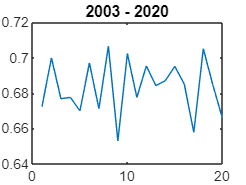

mes=[];
ps_1=[];
eage=[];
mean_eage=[];
pivot=1;
for i=init:finish
    eage{pivot}=find(info_hdf.anio==i);
    mean_eage(pivot)=mean(arr_ndvi(:,:,eage{pivot}),"all","omitnan");
    pivot=pivot+1;
end

plot(1:size(mean_eage,2),mean_eage);

title('2003 - 2020')


% mean_data=arr_ndvi(:,:,mean_eage(1,1));


Carga de archivos de datos

production = struct(...
    'Municipio',{'Cazones de Herrera', 'Chicontepec', 'Martínez de La Torre','Papantla','Tantoyuca','Tempoal','Tepetzintla','Tihuatlán','Tuxpan','Álamo Temapache'},...
    'Superficie_sembrada_Ha',[2827.00, 2820.00, 2820.00, 2596.00, 3191.00, 3191.00, 3198.00,3191.00,3191.00,3241.00,3241.00,3261.00,3281.00,3266.00,3278.00,3275.00,3278.00,3282.00,3282.00,3282.00] , ...
    'Superficie_cosechada_Ha',[0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00] , ...
    'Produccion_Ton',[0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00] , ...
    'Rendimiento_Ha',[0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00] , ...
    'Valor_Prod',[0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00,0.00] ...
);



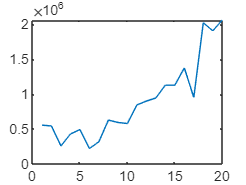


plot(production(10).Valor_Prod);



x=arr_ndvi(:,:,eage{1});

mean(arr_ndvi(:,:,eage{1}),"all","omitnan")

ans = 0.6724